# 5주차 — 안정도와 정상상태 오차

**제어시스템설계** · 충남대학교 자율운항시스템공학과

**참고자료 — 먼저 볼 것**

아래 다섯 과목은 **이 강의의 담당교수가 직접 한 강의**입니다. 기초부터 대학원 과정까지 이어지므로 부족한 곳부터 보면 됩니다. 이 강의에서 쓰는 기호와 유도는 모두 그 안에서 자세히 다룹니다.

**MATLAB 이나 Simulink 가 아직 익숙하지 않다면** 실습에 들어가기 전에 아래를 먼저 하십시오. 무료이고 각각 몇 시간이면 끝납니다.

1주차에서 두 가지를 미뤄 뒀습니다. 오늘 둘 다 해결합니다.

- "$K$ 를 무한히 키우면 안 된다" — **얼마까지 되는가?**

- "오차가 남는다" — **왜 남고 어떻게 없애는가?**

그리고 오늘의 진짜 주제는 이 둘이 **서로 반대 방향**이라는 것입니다.

- 오차를 없애려면 적분기가 필요하다

- 적분기를 넣으면 불안정해지기 쉽다

이 맞바꿈을 다루는 것이 앞으로 남은 주차의 내용입니다.

if isempty(which('plant_msd'))   % 경로가 아직 등록 안 되었으면 알아서 잡는다
    p_ = pwd;
    if ~isempty(mfilename('fullpath')), p_ = fileparts(mfilename('fullpath')); end
    for k_ = 1:4
        if isfile(fullfile(p_,'setup_path.m')), run(fullfile(p_,'setup_path.m')); break; end
        p_ = fileparts(p_);
    end
    clear p_ k_
end
clc; close all;
s = tf('s');

## 0-0. 오늘 돌려 볼 파일

강의노트를 읽다가 **직접 값을 바꿔 보고 싶을 때** 여는 파일들입니다. 모두 `W05_Stability_SSError` 폴더 안에 있습니다.

실행하는 법 — 파일을 열고 절 안에서 `Ctrl+Enter` 를 누르면 그 절만 돕니다. 전체는 `F5` 입니다. 처음 한 번은 `setup_path` 를 먼저 실행하십시오.

이 강의노트의 **그림은 전부** `make_figures.m` 이 만들어 `common/figures/` 에 넣어 둔 것입니다. 그림마다 어느 함수가 만들었는지 아래에 적어 두었습니다.

## 0. 오늘 한 장 요약

오늘은 **서로 반대 방향으로 당기는 두 가지**를 배웁니다.

- **안정도** — 이득을 키우면 언젠가 발산한다. 어디까지 키울 수 있는가?

- **정상상태 오차** — 이득을 키우면 정확해진다. 얼마나 정확해지는가?

즉 이득 하나를 두고 **정확도와 안정도가 줄다리기**를 합니다.

오늘의 계단

- **2절** 안정도. `roots` 로 극점을 보고, 3차 조건으로 임계이득을 손 계산

- **3~6절** 정상상태 오차. 시스템 타입과 오차상수

- **7~8절** 오차를 없애려면 무엇을 잃는가

- **10절** Simulink 로 적분기를 켜고 끄며 확인

오늘 딱 하나만 기억한다면 이것입니다.

- **오차를 없애는 일과 안정하게 만드는 일은 서로 반대 방향으로 당긴다**

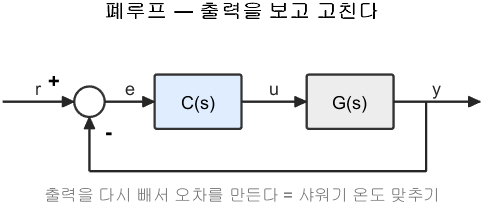

폐루프 — 출력을 보고 고친다

**그림 파일** `loop_closed.png` — `common/dg_loop.m` 의 `dg_loop` · 다시 만들려면 `make_figures('loop_closed')`

**만드는 곳** — `common/dg_loop.m` 을 `dg_loop('closed', ...)` 로 부릅니다

그림 해석

이 루프 모양은 학기 내내 바뀌지 않습니다. 바뀌는 것은 $C(s)$** 안에 무엇을 적는가**뿐입니다.

## 0-1. 가장 작은 예부터 — 이득을 키우면 무슨 일이 생기나

이해를 돕기 위해 제일 쉬운 것부터 봅니다.


$$G(s) = \frac{1}{s(s+1)(s+3)}$$


이득을 키워 가며 두 가지만 봅니다. **정상상태 오차**와 **극점의 위치**입니다.

G0 = 1/(s*(s+1)*(s+3));
fprintf('=== 이득을 키우면 ===\n');

=== 이득을 키우면 ===


fprintf('     K    가장 오른쪽 극점 실수부   오버슈트[%%]   판정\n');

     K    가장 오른쪽 극점 실수부   오버슈트[%]   판정


fprintf('  ------  ----------------------  -----------  --------\n');

  ------  ----------------------  -----------  --------


for K = [1 5 10 12 14]
    T  = feedback(K*G0, 1);
    mx = max(real(pole(T)));
    if mx < 0
        v = '안정';  os = getfield(stepinfo(T), 'Overshoot'); %#ok<GFLD>
    else
        v = '불안정'; os = NaN;
    end
    fprintf('  %6.1f  %22.4f  %11.1f  %s\n', K, mx, os, v);
end

     1.0                 -0.4261          2.6  안정
     5.0                 -0.2241         51.6  안정
    10.0                 -0.0552         82.9  안정


    12.0                 -0.0000          NaN  안정
    14.0                  0.0505          NaN  불안정


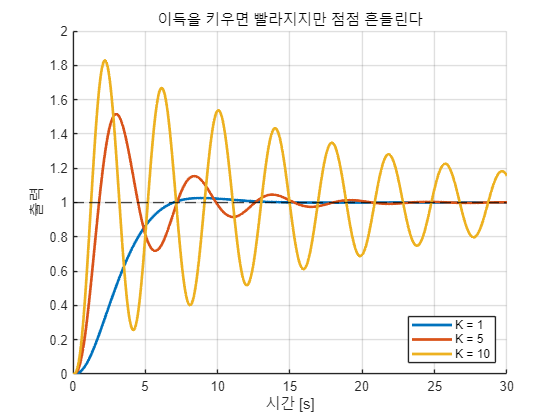

t0 = (0:0.05:30)';
figure;
hold on; grid on;
for K = [1 5 10]
    plot(t0, step(feedback(K*G0,1), t0), 'LineWidth', 2, ...
         'DisplayName', sprintf('K = %d', K));
end
yline(1,'k--','HandleVisibility','off');
xlabel('시간 [s]'); ylabel('출력'); ylim([0 2]);
legend('Location','southeast');
title('이득을 키우면 빨라지지만 점점 흔들린다');

이 표에서 오늘 배울 것이 다 보입니다.

- 이득을 키우면 극점이 **오른쪽으로** 움직인다

- 어느 값을 넘으면 실수부가 $+$ 가 되어 **발산**한다

- 그 경계값을 **임계이득** 이라고 합니다. 손으로 구하는 법을 2절에서 배웁니다

## 1. 오늘의 플랜트 — DC 모터

5주차부터 11주차까지 DC 모터를 씁니다. 먼저 어떻게 생긴 물건인지 봅니다.

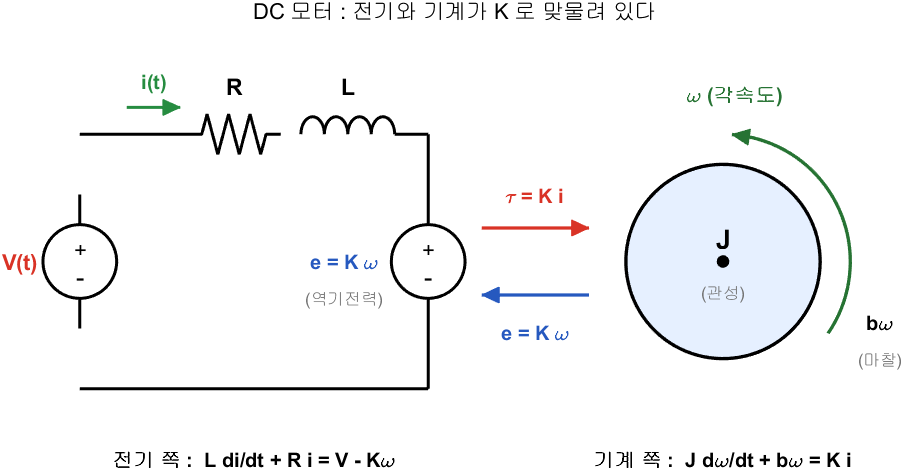

DC 모터 : 전기와 기계가 K 로 맞물려 있다

**그림 파일** `motor_schematic.png` — `common/dg_motor.m` 의 `dg_motor` · 다시 만들려면 `make_figures('motor_schematic')`

**만드는 곳** — `common/dg_motor.m` (`make_figures('motor_schematic')`) **직접 확인해 보려면** — `W05_01_stability.m` 의 **1절**이 이 그림의 두 식에서 전달함수를 만들어 냅니다

그림 해석

**파란 화살표(역기전력)가 이 모터의 핵심**입니다. 이것 때문에 모터는 전압을 올려도 속도가 무한히 올라가지 않고 어느 값에서 멈춥니다. 모터 안에 이미 **되먹임이 들어 있는** 셈입니다.

## 1-0. 식이 왜 두 줄인가

DC 모터가 처음에 어려운 이유는 **전기와 기계가 맞물려 있기** 때문입니다. 위 그림에서 가운데 두 화살표가 맞물리는 자리입니다.

- **전기 **$\rightarrow$** 기계** : 전류가 흐르면 토크가 난다.  $\tau = K\,i$

- **기계 **$\rightarrow$** 전기** : 빨리 돌면 역기전력이 생긴다.  $e = K\,\omega$

그래서 식이 두 줄이고 서로를 참조합니다.


$$L\,\frac{di}{dt} + R\,i = V - K\,\omega \qquad (\text{전기 쪽, 키르히호프})$$



$$J\,\frac{d\omega}{dt} + b\,\omega = K\,i \qquad (\text{기계 쪽, 뉴턴})$$


두 식을 라플라스 변환해 $I(s)$ 를 소거하면 전달함수가 나옵니다.


$$\frac{\Omega(s)}{V(s)} = \frac{K}{(Ls+R)(Js+b) + K^2}$$


**역기전력이 **$K^2$** 항을 만든다** 는 점이 중요합니다. 모터가 빨리 돌수록 스스로 브레이크를 거는 셈이라 자연스럽게 안정해집니다.

## 1-1. 두 가지 모델

위 식은 **속도** 모델입니다. 여기서 두 가지를 씁니다.

- **속도 모델** — 입력 전압, 출력 각속도

- **위치 모델** — 입력 전압, 출력 각도. 속도 모델을 $s$ 로 한 번 더 나눈 것

왜 둘을 구분하는가

- 각도는 각속도의 적분이므로 위치 모델에는 **적분기가 이미 들어 있다**

- 이 적분기가 오늘 이야기의 주인공이다

물리 모델은 이렇습니다.


$$L\frac{di}{dt} + Ri = V - K_e\omega, \qquad J\frac{d\omega}{dt} + b\omega = K_t i$$


정리하면 속도 모델의 전달함수가 나옵니다.


$$G(s) = \frac{\omega(s)}{V(s)} = \frac{K}{(Js+b)(Ls+R)+K^2}$$


[Gs, ps] = plant_dcmotor('speed');
[Gp, pp] = plant_dcmotor('position');
Gs


Gs =
 
  입력 "V"에서 출력 "w"(으)로:
             0.01
  ---------------------------
  0.005 s^2 + 0.06 s + 0.1001
 
연속시간 전달 함수입니다.


fprintf('속도 모델 극점 : ');  fprintf('%+.3f ', pole(Gs)); fprintf('\n');

속도 모델 극점 : -9.997 -2.003 


fprintf('위치 모델 극점 : ');  fprintf('%+.3f ', pole(Gp)); fprintf('\n');

위치 모델 극점 : +0.000 -9.997 -2.003 


## 2. 안정도 — 얼마까지 키울 수 있는가

안정하다는 것의 정의는 2주차에서 배웠습니다.

- 극점이 **전부 좌반면**에 있으면 안정

- 하나라도 **우반면**에 있으면 불안정

오늘 새로 다루는 것은 이것입니다.

- 제어이득 $K$ 를 바꾸면 **폐루프 극점이 움직인다**

- 그러다 어느 순간 우반면으로 넘어간다

- 그 $K$ 를 **임계이득**이라 한다

## 2-1. `roots` — 다항식의 근 구하기

새로 나오는 명령입니다.

- **하는 일** — 다항식의 근을 구한다

- **입력** — 계수 벡터. $s$ 의 **높은 차수부터** 나열

- **출력** — 근을 담은 열벡터

주의

- `roots` 는 **전달함수가 아니라 계수 벡터**를 받는다

- 전달함수에서 계수를 꺼내려면 `tfdata(G, 'v')` 를 쓴다

- `pole(G)` 와 혼동하지 말 것. `pole` 은 전달함수를, `roots` 는 계수를 받는다

왜 `roots` 가 필요한가

- 폐루프 특성방정식은 $1 + KG(s) = 0$, 즉 분모 $+$ $K\times$분자 $=0$ 이다

- $K$ 가 바뀌면 계수가 바뀌므로 매번 근을 다시 구해야 한다

- `feedback` 을 쓰고 `pole` 을 불러도 되지만, 계수를 직접 만지면 $K$ 가 어디에 들어가는지 눈에 보인다

fprintf('roots 예시 : s^2 + 3s + 2 = 0 의 근\n');

roots 예시 : s^2 + 3s + 2 = 0 의 근


disp(roots([1 3 2]))

    -2
    -1



## 2-2. $K$ 를 키우면 극점이 어디로 가는가

위치 모델(3차)에 대해 $K$ 를 $0$ 부터 $300$ 까지 키우며 극점을 추적합니다.

보이는 것

- 원점에서 출발한 극점 두 개가 서로 만나 복소수가 된다

- 그다음 오른쪽으로 휘어져 올라간다

- 어느 순간 **허수축을 넘는다** — 여기가 불안정의 시작

이 그림이 바로 다음 주에 배울 **근궤적**입니다.

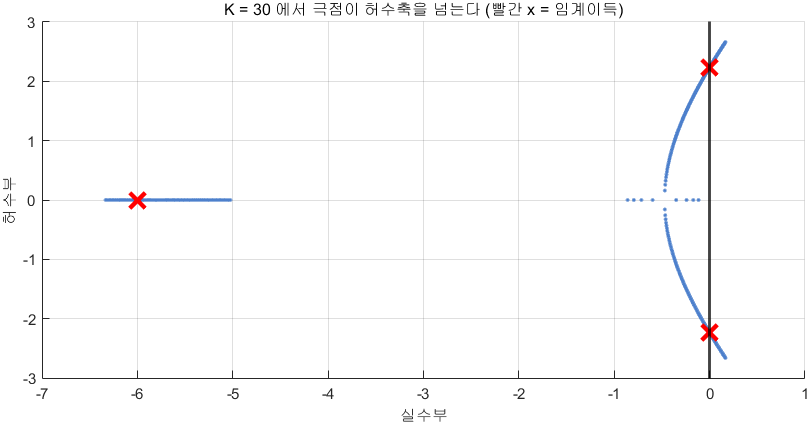

K 를 키우면 극점이 허수축을 넘어간다

**그림 파일** `w05_gain_poles.png` — `make_figures.m` 의 `fig_gain_poles` · 다시 만들려면 `make_figures('w05_gain_poles')`

**만드는 곳** — `make_figures.m` 의 `fig_gain_poles` **직접 바꿔 보려면** — `W05_01_stability.m` 의 **2절**에서 `Ks` 의 범위를 `linspace(0,600,600)` 처럼 넓혀 실행

그림 해석

이 그림이 그대로 **6주차의 근궤적**입니다. 오늘은 점을 찍어서 그렸지만, 6주차에서는 `rlocus` 한 줄로 그리고 **작도 규칙**으로 손으로도 그립니다.

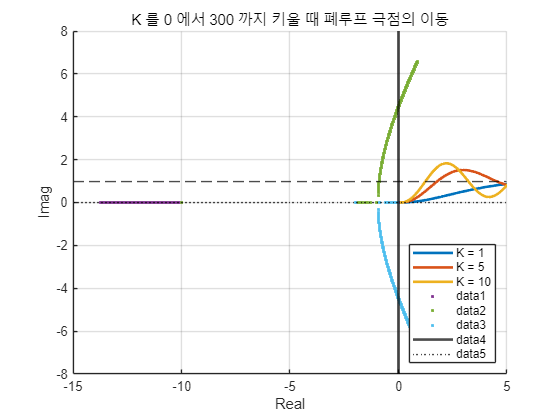

[numP, denP] = tfdata(Gp, 'v');
Ks = linspace(0,300,600);
R = zeros(numel(denP)-1, numel(Ks));
for i=1:numel(Ks)
    R(:,i) = roots(denP + Ks(i)*[zeros(1,numel(denP)-numel(numP)) numP]);
end
for j=1:size(R,1)
    plot(real(R(j,:)), imag(R(j,:)), '.', 'MarkerSize', 6); hold on
end
xline(0,'k-','LineWidth',2); yline(0,'k:')
grid on; xlabel('Real'); ylabel('Imag')
title('K 를 0 에서 300 까지 키울 때 폐루프 극점의 이동')
xlim([-15 5]); ylim([-8 8])

## 2-3. 임계이득을 손으로 구하기

3차 다항식에는 아주 간단한 안정 조건이 있습니다.


$$a_3 s^3 + a_2 s^2 + a_1 s + a_0 = 0$$


이 식이 안정할 조건은

- 모든 계수가 **같은 부호이고 **$0$** 이 아니다**

- 
$$a_2 a_1 > a_3 a_0$$


두 번째가 핵심 조건입니다. 그런데 **이 조건이 어디서 나왔는지**를 모르고 외우면 4차 이상에서 아무것도 못 합니다. 다음 절에서 만들어 봅니다.

우리 시스템에 적용하면

a3 = denP(1); a2 = denP(2); a1 = denP(3); b0 = numP(end);
fprintf('특성방정식 : %.4f s^3 + %.4f s^2 + %.4f s + %.4f K = 0\n', a3,a2,a1,b0);

특성방정식 : 0.0050 s^3 + 0.0600 s^2 + 0.1001 s + 0.0100 K = 0


fprintf('조건 : a2*a1 > a3*b0*K  ->  K < %.2f\n', (a2*a1)/(a3*b0));

조건 : a2*a1 > a3*b0*K  ->  K < 120.12


## 2-3-1. 그 조건은 어디서 나왔는가 — 라우스 표

3학년 제어공학에서 배운 **라우스 표**입니다. 다시 세워 봅니다. 표를 만드는 규칙은 두 줄뿐입니다.

- 첫 두 줄은 계수를 **하나씩 건너뛰며** 적는다

- 그 아래 줄부터는 바로 위 두 줄에서 $2\times2$** 행렬식을 만들어 바로 왼쪽 아래 값으로 나눈 뒤 부호를 뒤집는다**

판정은 한 줄입니다.

**첫 번째 열의 부호가 한 번도 안 바뀌면 안정하다.** 부호가 바뀐 횟수가 곧 **우반면 극점의 개수**입니다.

3차 $a_3 s^3 + a_2 s^2 + a_1 s + a_0 = 0$ 에 대해 만들면 이렇습니다.

첫째 열이 전부 양수여야 하므로 조건이 두 개 나옵니다.

- $a_0 > 0$ — 상수항이 양수

- $a_2 a_1 - a_3 a_0 > 0$ — 즉 $a_2 a_1 > a_3 a_0$

**앞 절에서 그냥 받아 적은 조건이 바로 이 **$s^1$** 행입니다.**

우리 DC 모터에 넣어 보면 $a_0 = 0.01K$ 이므로


$$s^1 \text{ 행} = \frac{0.06 \times 0.1001 - 0.005 \times 0.01K}{0.06} = \frac{0.006006 - 0.00005\,K}{0.06}$$


이것이 양수여야 하므로 $K < 0.006006/0.00005 = 120.12$ 입니다.

routh3 = [a3, a1; a2, b0];      % K 를 곱하기 전의 상수항 계수
fprintf('\n=== 라우스 표 (3차) ===\n');


=== 라우스 표 (3차) ===


fprintf('  s^3 |  %10.6f  %10.6f\n', a3, a1);

  s^3 |    0.005000    0.100100


fprintf('  s^2 |  %10.6f  %10.6f K\n', a2, b0);

  s^2 |    0.060000    0.010000 K


fprintf('  s^1 |  (%.6f - %.6f K) / %.4f\n', a2*a1, a3*b0, a2);

  s^1 |  (0.006006 - 0.000050 K) / 0.0600


fprintf('  s^0 |  %10.6f K\n', b0);

  s^0 |    0.010000 K


fprintf('  --> 첫째 열이 모두 양수 :  0 < K < %.4f\n\n', (a2*a1)/(a3*b0));

  --> 첫째 열이 모두 양수 :  0 < K < 120.1200



## 2-3-2. 4차는 표를 한 줄 더 만들면 된다

3차만 외우면 4차에서 막힙니다. 규칙은 똑같으니 한 번 더 해 봅니다.


$$s^4 + 2s^3 + 3s^2 + 4s + K = 0$$


첫째 열이 전부 양수여야 하므로

- 
$$K > 0$$


- 
$$4 - 2K > 0 \;\Rightarrow\; K < 2$$


즉 $0 < K < 2$ 입니다. `roots` 로 확인해 보면 정확히 맞습니다.

fprintf('=== 4차 예제 : s^4 + 2s^3 + 3s^2 + 4s + K ===\n');

=== 4차 예제 : s^4 + 2s^3 + 3s^2 + 4s + K ===


for Kt = [1.9 2.0 2.1]
    rt = roots([1 2 3 4 Kt]);
    if max(real(rt)) < -1e-9, st = '안정'; elseif max(real(rt)) > 1e-9, st = '불안정';
    else, st = '임계'; end
    fprintf('  K = %.1f  최대 실수부 %+.4f  -> %s\n', Kt, max(real(rt)), st);
end

  K = 1.9  최대 실수부 -0.0111  -> 안정
  K = 2.0  최대 실수부 +0.0000  -> 임계
  K = 2.1  최대 실수부 +0.0111  -> 불안정


fprintf('  --> 라우스가 예측한 경계 K = 2 와 정확히 같습니다.\n\n');

  --> 라우스가 예측한 경계 K = 2 와 정확히 같습니다.



## 2-3-3. 같은 임계이득을 세 가지 방법으로

임계이득을 구하는 방법이 이 과목에 셋 있습니다. **답이 같아야 하고, 같은지 확인하는 것 자체가 검증입니다.**

두 번째 방법을 미리 해 보면 이렇습니다. $s = j\omega$ 를 넣고 정리하면

- 허수부 : $-a_3\omega^3 + a_1\omega = 0 \;\Rightarrow\; \omega = \sqrt{a_1/a_3}$

- 실수부 : $-a_2\omega^2 + a_0 = 0 \;\Rightarrow\; K = a_2\omega^2/b_0$

**라우스는 **$K$** 만 주지만, 이 방법은 그때의 진동 주파수 **$\omega$** 도 줍니다.** 임계이득에서 시스템이 어떤 주기로 떨리는지까지 알 수 있다는 뜻입니다.

w_c   = sqrt(a1/a3);
K_jw  = a2*w_c^2/b0;
K_rou = (a2*a1)/(a3*b0);
Ksweep = linspace(100, 140, 40001);
idx = find(arrayfun(@(K) max(real(roots(denP + [0 0 0 K*b0]))) > 0, Ksweep), 1);

fprintf('=== 세 가지 방법 대조 ===\n');

=== 세 가지 방법 대조 ===


fprintf('  라우스 표     : K = %.4f\n', K_rou);

  라우스 표     : K = 120.1200


fprintf('  s = jw 대입   : K = %.4f  (w = %.4f rad/s, 주기 %.3f s)\n', ...
        K_jw, w_c, 2*pi/w_c);

  s = jw 대입   : K = 120.1200  (w = 4.4744 rad/s, 주기 1.404 s)


fprintf('  roots 훑기    : K = %.4f\n', Ksweep(idx));

  roots 훑기    : K = 120.1200


fprintf('  그 K 의 극점  : %s\n', ...
        mat2str(round(roots(denP + [0 0 0 K_rou*b0]).', 4)));

  그 K 의 극점  : [-12 0+4.4744i 0-4.4744i]


fprintf('  --> 실수부가 0 인 극점 한 쌍. 세 방법이 모두 같습니다.\n\n');

  --> 실수부가 0 인 극점 한 쌍. 세 방법이 모두 같습니다.



## 2-4. 속도 모델은 왜 불안정해지지 않는가

같은 실험을 속도 모델로 하면 $K$ 를 아무리 키워도 안정합니다.

이유는 **차수**입니다.

- 속도 모델은 **2차** — 특성방정식이 2차. 계수가 모두 양수면 항상 안정

- 위치 모델은 **3차** — 3차부터는 계수가 양수여도 불안정할 수 있다

2차 시스템에서 $K$ 를 키우면 상수항만 커지므로 계수 부호가 바뀌지 않습니다.

즉 **적분기 하나가 추가되면서 시스템이 훨씬 까다로워진 것**입니다. 이것이 다음 이야기로 이어집니다.

## 3. 정상상태 오차 — 왜 남는가

오차식을 세우기 전에 **오차 **$e$** 가 그림의 어디인지** 확인합니다.

오차 e 는 합산점 바로 뒤의 신호다

**그림 파일** `loop_closed.png` — `common/dg_loop.m` 의 `dg_loop` · 다시 만들려면 `make_figures('loop_closed')`

**만드는 곳** — `common/dg_loop.m` 을 `dg_loop('closed', ...)` 로 부릅니다

그림 해석 — **유도에 쓸 기호를 그림에서 하나씩 짚습니다**

이제 유도합니다. 그림에서 화살표를 따라가며 **두 줄**만 적으면 됩니다.


$$e = r - y, \qquad y = L\,e$$


둘째 식을 첫째에 넣습니다.


$$e = r - L\,e$$


$e$** 가 양변에 나왔으므로** 한쪽으로 모읍니다.


$$e + L\,e = r \qquad\Rightarrow\qquad (1 + L)\,e = r$$


양변을 $(1+L)$ 로 나누면 오차식이 나옵니다.


$$E(s) = \frac{R(s)}{1 + L(s)}$$


**1주차에서 본 **$(1+KG)$** 와 똑같은 자리**입니다. 그때는 $K$ 하나였고 지금은 제어기 전체 $L$ 이라는 차이뿐입니다.

이제 $t \to \infty$ 일 때의 값을 알고 싶습니다. 시간영역으로 역변환할 필요 없이 **최종값 정리**를 쓰면 됩니다.


$$\lim_{t\to\infty} e(t) = \lim_{s\to 0} s\,E(s)$$


오차식을 넣으면


$$e_{ss} = \lim_{s \to 0} \frac{s R(s)}{1 + L(s)}$$


핵심은 분모의 $L(0)$ 입니다.

- $L(0)$ 이 **유한**하면 오차가 남는다

- $L(0)$ 이 **무한대**면 오차가 $0$ 이 된다

$L(0)$ 을 무한대로 만들려면 $L(s)$ 의 분모에 $s$ 가 있으면 됩니다. $s=0$ 에서 $0$ 으로 나누게 되기 때문입니다. 그 분모의 $s$ 가 바로 **적분기**입니다.

## 3-1. 직관으로 보면

- **비례제어**는 오차가 있어야만 힘을 낸다. 오차가 $0$ 이면 힘도 $0$

- **적분제어**는 오차를 쌓아 둔다. 오차가 $0$ 이 되어도 쌓인 값이 남아 계속 힘을 낼 수 있다

그래서 적분제어는 오차를 $0$ 까지 밀어붙일 수 있습니다.

1주차에서 "오차가 제어기의 연료" 라고 했던 것을 떠올리십시오. 적분기는 **연료를 저장해 두는 탱크**인 셈입니다.

말로만 하면 잘 안 와닿으니 세 장을 나란히 놓고 보겠습니다. 특히 **세 번째 그림**을 보십시오. 여기가 핵심입니다.

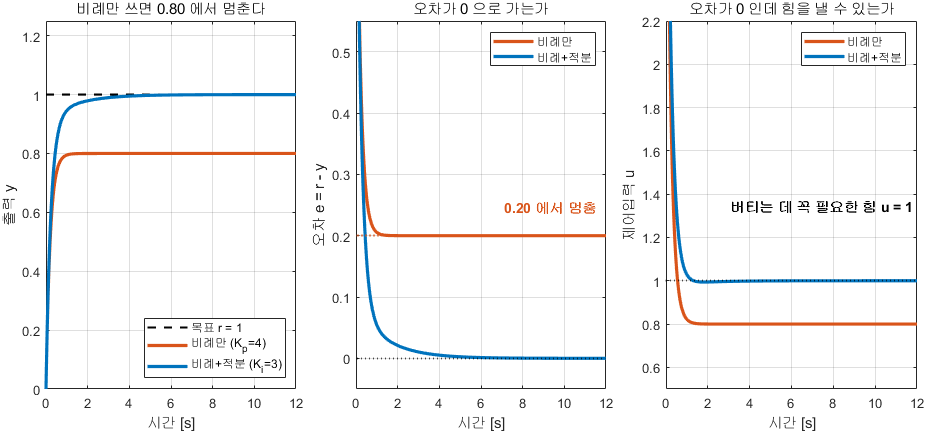

오차가 0 인데도 힘을 낼 수 있어야 오차가 0 으로 간다

**그림 파일** `w05_why_error.png` — `make_figures.m` 의 `fig_w05_why_error` · 다시 만들려면 `make_figures('w05_why_error')`

**만드는 곳** — `make_figures.m` 의 `fig_w05_why_error` **직접 바꿔 보려면** — `W05_02_steady_state_error.m` 에서 $K_i$ 를 $0$ 으로 두고 실행하면 왼쪽 그림의 빨간 곡선만 남습니다

그림 해석

**오른쪽 그림이 오늘의 논리 전체입니다.**

- 목표를 유지하려면 힘 $1$ 이 필요하다

- 비례제어는 $u = K_p e$ 이므로 $e=0$ 이면 $u=0$ 이 된다. **모순**이다

- 그래서 비례제어는 반드시 $e = 1/K_p \cdot 1 = 0.2$ 만큼 오차를 남겨야 힘 $0.8$ 을 낼 수 있다 (이 플랜트의 이득이 $1$ 이라 $0.8$ 이면 출력 $0.8$)

- 적분기는 **오차와 무관하게 쌓아 둔 값**으로 힘을 내므로 이 모순이 없다

같은 이야기를 **블록선도 위에서 신호를 따라가며** 확인하겠습니다. 위 그림들은 시간축이었고, 이번에는 **루프의 어느 자리**에서 벌어지는 일인지를 봅니다.

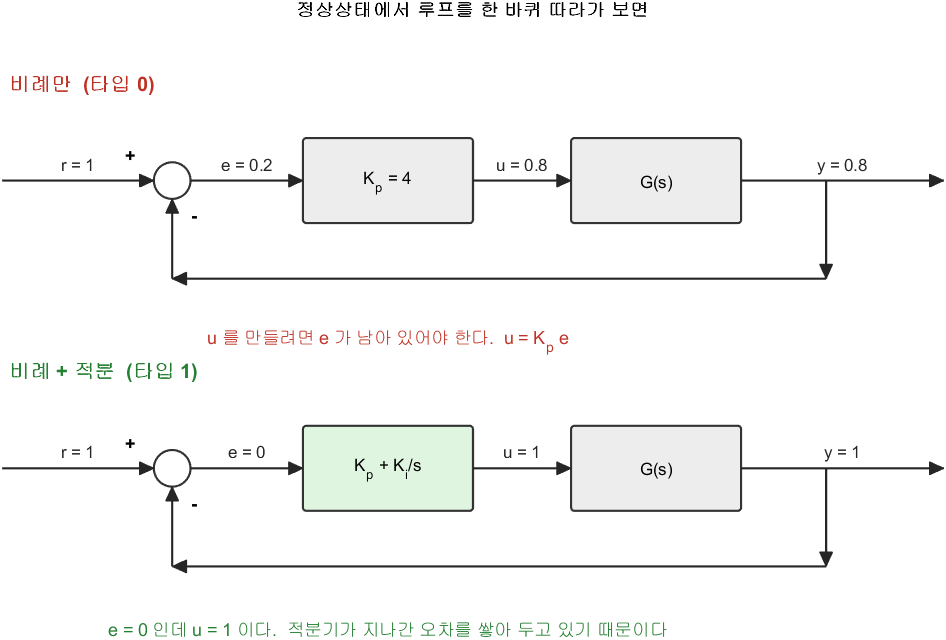

정상상태에서 루프 각 지점의 값

**그림 파일** `w05_type_signal.png` — `make_figures.m` 의 `fig_w05_type_signal` · 다시 만들려면 `make_figures('w05_type_signal')`

**만드는 곳** — `make_figures.m` 의 `fig_w05_type_signal` **직접 확인해 보려면** — `W05_02_steady_state_error.m` 의 **1절**이 같은 두 경우의 정상상태 값을 계산해 출력합니다

그림 해석

두 그림의 차이는 제어기 블록 하나뿐입니다. 그런데 그 하나가 $e$ 와 $u$ 의 관계를 바꿉니다.

- 비례만 — $u$ 는 **지금의 **$e$ 에 묶여 있다. $e=0$ 이면 $u=0$

- 적분 포함 — $u$ 는 $e$** 의 이력**에 묶여 있다. $e=0$ 이어도 $u$ 는 남는다

이 한 문장이 시스템 타입의 정의로 이어집니다.

## 4. 시스템 타입

개루프 전달함수를 이렇게 씁니다.


$$L(s) = \frac{K \cdot (\text{분자})}{s^N \cdot (\text{분모})}$$


단, 분자와 분모는 $s=0$ 에서 $0$ 이 아닙니다. 이 $N$ 을 **시스템 타입**이라 하며, 원점 극점(적분기)의 개수입니다.

- 타입 0 — 적분기 없음. DC 모터 **속도** 모델

- 타입 1 — 적분기 1개. DC 모터 **위치** 모델

- 타입 2 — 적분기 2개

위치 모델이 타입 1 인 이유는 각도가 각속도의 적분이기 때문입니다. **물리적으로 적분기가 이미 들어 있는** 셈입니다.

## 5. 오차상수 — $K_p$, $K_v$, $K_a$

입력 종류마다 오차를 계산하는 상수가 따로 있습니다. 전부 "$L(s)$ 에 $s$ 를 몇 개 곱하고 $s=0$ 대입" 입니다.


$$K_p = \lim_{s\to 0} L(s), \qquad K_v = \lim_{s\to 0} s L(s), \qquad K_a = \lim_{s\to 0} s^2 L(s)$$


그리고 오차는


$$e_{step} = \frac{1}{1+K_p}, \qquad e_{ramp} = \frac{1}{K_v}, \qquad e_{para} = \frac{1}{K_a}$$


MATLAB 에서는 `dcgain` 으로 극한을 구합니다.

- `Kp = dcgain(L)`

- `Kv = dcgain(s*L)`

- `Ka = dcgain(s^2*L)`

**주의** — `dcgain` 은 극한이 무한대면 `Inf` 를 돌려줍니다. 오류가 아닙니다. `Inf` 는 **그 입력에 대해 오차가 **$0$ 이라는 좋은 소식입니다.

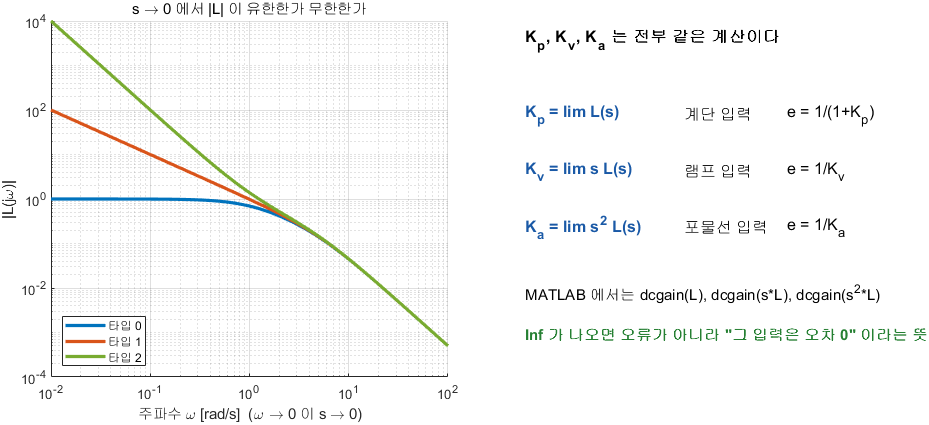

세 상수는 s 를 몇 개 곱하느냐만 다르다

**그림 파일** `w05_error_const.png` — `make_figures.m` 의 `fig_w05_error_const` · 다시 만들려면 `make_figures('w05_error_const')`

**만드는 곳** — `make_figures.m` 의 `fig_w05_error_const` **직접 바꿔 보려면** — `W05_02_steady_state_error.m` 의 **3절**에서 `dcgain(L)`, `dcgain(s*L)`, `dcgain(s^2*L)` 를 직접 찍어 보십시오

그림 해석

K = 50;
Ls = {K*Gs, K*Gp, K*Gp/s};
nm = {'타입 0','타입 1','타입 2'};
for i=1:3
    fprintf('%s : Kp=%8.3f  Kv=%8.3f  Ka=%8.3f\n', nm{i}, ...
            dcgain(Ls{i}), dcgain(s*Ls{i}), dcgain(s^2*Ls{i}));
end

타입 0 : Kp=   4.995  Kv=   0.000  Ka=   0.000
타입 1 : Kp=     Inf  Kv=   4.995  Ka=   0.000
타입 2 : Kp=     Inf  Kv=     Inf  Ka=   4.995


## 6. 타입과 입력의 대응 — 규칙 하나

표를 외울 필요는 없습니다. 규칙 하나면 됩니다.

**타입 **$N$** 은 **$N$** 차까지의 입력을 오차 없이 따라간다**

- 타입 0 — 계단(0차)도 못 따라감. 오차가 유한하게 남는다

- 타입 1 — 계단은 완벽. 램프(1차)는 오차가 유한하게 남는다

- 타입 2 — 계단과 램프 완벽. 포물선(2차)은 오차가 유한하게 남는다

그리고 **자기 차수보다 높은 입력은 무한히 벌어집니다.**

실무에서 이것이 뜻하는 것

- 위치를 일정한 값으로 유지하고 싶다 → 타입 1 이면 충분

- 일정한 속도로 따라가고 싶다 (램프 추종) → 타입 2 가 필요

- 예: 위성 안테나가 별을 추적하려면 타입 2 가 있어야 한다

## 6-1. 표를 그림으로 — 아홉 칸을 한꺼번에

타입 0, 1, 2 에 계단 · 램프 · 포물선을 각각 넣어 봅니다. **파란 선이 지령, 빨간 선이 출력**이고 둘 사이 간격이 오차입니다.

한 칸씩 보지 말고 **대각선**을 보십시오. 왼쪽 위에서 오른쪽 아래로 갈수록 오차가 커집니다. 그것이 규칙 그대로입니다.

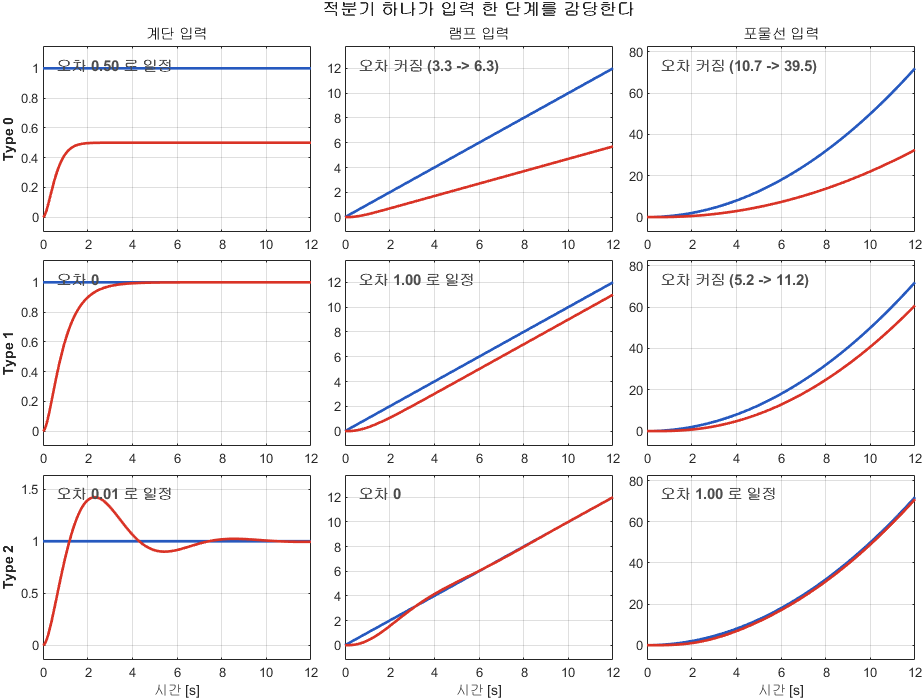

적분기 하나가 입력 한 단계를 감당한다

**그림 파일** `w05_type_table.png` — `make_figures.m` 의 `fig_type_table` · 다시 만들려면 `make_figures('w05_type_table')`

**만드는 곳** — `make_figures.m` 의 `fig_type_table` **직접 바꿔 보려면** — 바로 아래 코드가 같은 그림을 그립니다. `Ls_type` 에 타입 3 을 하나 더 넣어 보십시오

그림 해석 — **왼쪽 위에서 오른쪽 아래로 대각선을 따라 읽으십시오**

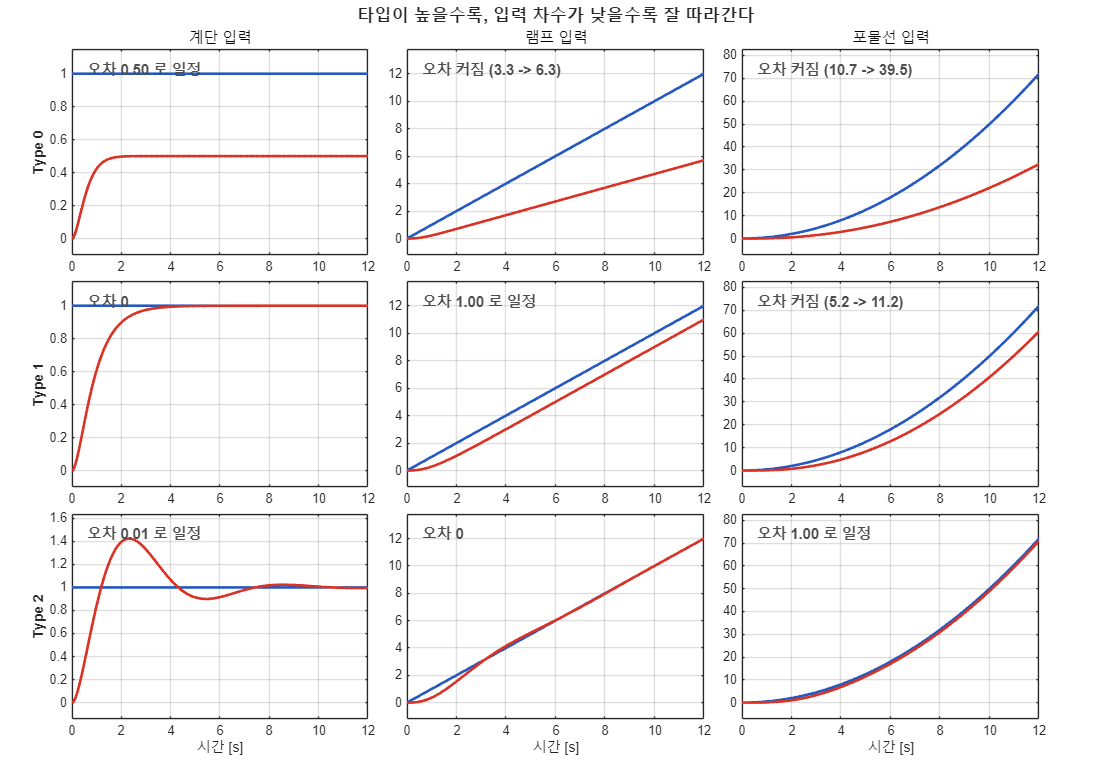

Ls_type = { 'Type 0',  5/((s+1)*(s+5))
            'Type 1',  5/(s*(s+5))
            'Type 2',  5*(s+1)/(s^2*(s+5)) };
in_name = {'계단', '램프', '포물선'};
tt = (0:0.05:12)';
inputs = { ones(size(tt)), tt, 0.5*tt.^2 };
figure('Position',[60 60 1100 760]);
tiledlayout(3,3,'TileSpacing','compact','Padding','compact');
for a = 1:3
    for b = 1:3
        nexttile
        T = feedback(Ls_type{a,2}, 1);
        u = inputs{b};
        if all(real(pole(T)) < 0)
            y = lsim(T, u, tt);
        else
            y = nan(size(tt));
        end
        plot(tt, u, 'LineWidth', 2, 'Color', [0.15 0.35 0.75]); hold on;
        plot(tt, y, 'LineWidth', 2, 'Color', [0.85 0.20 0.15]);
        grid on; xlim([0 12]);
        ymax = max([u; y(~isnan(y))]);
        ylim([-0.1*ymax 1.15*ymax]);
        if a == 1, title(sprintf('%s 입력', in_name{b}), 'FontSize', 11); end
        if b == 1, ylabel(Ls_type{a,1}, 'FontWeight','bold'); end
        if a == 3, xlabel('시간 [s]'); end
        % 마지막 오차를 글자로.
        % "커진다" 는 판정은 크기가 아니라 절반 시점과 견주어 정한다.
        % 크기로만 보면 타입 0 + 계단(오차 0.50 으로 일정) 이 잘못 걸린다.
        e_end  = u(end) - y(end);
        e_half = u(round(end/2)) - y(round(end/2));
        if isnan(e_end)
            txt = '불안정';
        elseif abs(e_end) < 5e-3
            txt = '오차 0';
        elseif abs(e_end) > abs(e_half)*1.3 + 1e-6
            txt = sprintf('오차 커짐 (%.1f -> %.1f)', e_half, e_end);
        else
            txt = sprintf('오차 %.2f 로 일정', e_end);
        end
        text(0.05, 0.90, txt, 'Units','normalized', 'FontSize', 11, ...
             'FontWeight','bold', 'Color', [0.3 0.3 0.3]);
    end
end
sgtitle('타입이 높을수록, 입력 차수가 낮을수록 잘 따라간다', ...
        'FontSize', 13, 'FontWeight','bold');

그림에서 확인할 것

- **대각선 위쪽** (타입 $>$ 입력 차수) — 오차가 $0$. 완벽하게 겹친다

- **대각선** (타입 $=$ 입력 차수) — 일정한 간격이 남는다

- **대각선 아래쪽** (타입 $<$ 입력 차수) — 간격이 점점 벌어진다

이 아홉 칸이 앞의 표와 정확히 같습니다.

## 7. 그런데 공짜가 아니다

여기가 오늘의 결론입니다.

2절에서 본 것과 합쳐 보면

- 타입 0 (속도 모델, 2차) — $K$ 를 아무리 키워도 **안정**

- 타입 1 (위치 모델, 3차) — $K$ 가 약 $122$ 를 넘으면 **불안정**

- 타입 2 (위치 모델에 적분기 하나 더, 4차) — **어떤 **$K$** 로도 안정화되지 않는다**

마지막 줄은 과장이 아닙니다. 특성방정식을 써 보면 $s$ 의 1차 항 계수가 $0$ 이 되어, 계수가 전부 양수여야 한다는 **필요조건부터** 깨집니다. 비례이득 하나만으로는 손을 쓸 수가 없습니다. 이럴 때 쓰는 것이 7주차의 보상기와 11주차의 PID 입니다.

**타입이 올라갈수록 안정도가 나빠집니다.**

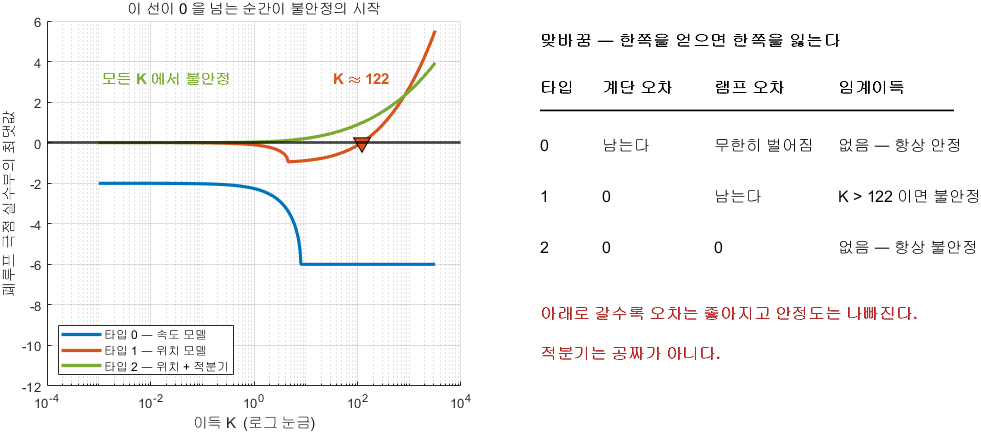

적분기를 넣을수록 임계이득이 내려간다

**그림 파일** `w05_tradeoff.png` — `make_figures.m` 의 `fig_w05_tradeoff` · 다시 만들려면 `make_figures('w05_tradeoff')`

**만드는 곳** — `make_figures.m` 의 `fig_w05_tradeoff` **직접 확인해 보려면** — `W05_01_stability.m` 의 **3절**이 같은 계산을 3차 안정 조건으로 손계산해 대조합니다

그림 해석

왜 그런가

- 적분기는 원점에 극점을 하나 더 놓는 것이다

- 원점 극점은 위상을 $90^\circ$ 늦춘다

- 위상이 늦어지면 되먹임 신호가 제때 도착하지 못해 불안정에 가까워진다

- (위상이라는 말은 9~10주차에서 제대로 다룹니다)

매우 중요한 단서

- 오차 공식은 **폐루프가 안정할 때만** 의미가 있다

- 불안정한 시스템은 정상상태 자체가 없다

- 표를 쓰기 전에 반드시 안정한지부터 확인할 것

## 8. 그래서 실무에서는

정상상태 오차와 안정도가 맞바꿈이므로 두 방향이 있습니다.

- **적분기를 넣되 다른 것으로 안정도를 보완한다** PI 에 D 를 더한 PID (11주차), 원점 "근처" 에 극점을 두는 지상보상기 (7주차)

- **애초에 적분기 없이 이득만 키운다** 오차는 남지만 안정하다. 허용 범위 안이면 이것으로 충분하다

어느 쪽을 고를지는 **사양이 정합니다.** "정상상태 오차 $0$" 이 요구사항에 있으면 앞쪽, 아니면 뒤쪽으로 충분합니다.

## 9. 1주차의 $K_r$ 은 무엇이었나

1주차에서 폐루프에 $K_r$ 을 곱해 오차를 없앴습니다. 적분기와 무엇이 다른가?

- $K_r$** 방식** — 계산으로 미리 보정한다. 모델을 정확히 알아야 한다. 모델이 틀리면 오차가 다시 생긴다

- **적분기** — 오차를 보고 스스로 없앤다. 모델이 틀려도 오차가 $0$ 이 된다

즉 $K_r$ 은 **개루프식 보정**, 적분기는 **폐루프식 보정**입니다. 1주차의 교훈 그대로, 모델이 틀리면 $K_r$ 은 무너집니다.

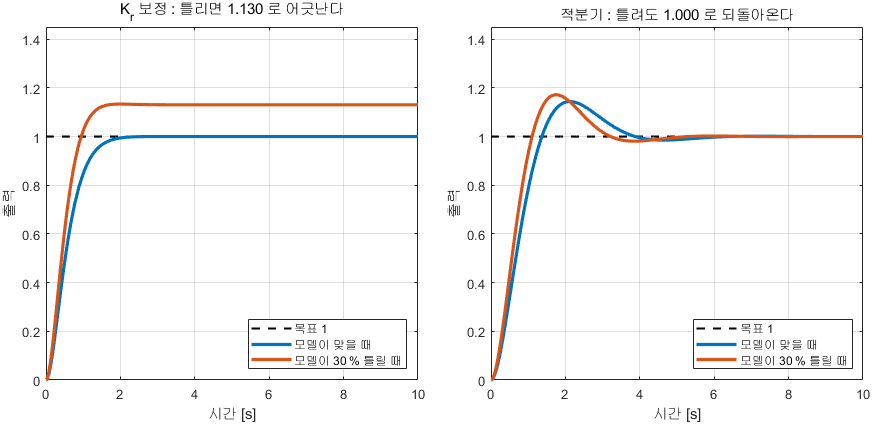

모델이 틀렸을 때 갈린다

**그림 파일** `w05_kr_vs_int.png` — `make_figures.m` 의 `fig_w05_kr_vs_int` · 다시 만들려면 `make_figures('w05_kr_vs_int')`

**만드는 곳** — `make_figures.m` 의 `fig_w05_kr_vs_int` **직접 바꿔 보려면** — 함수 안의 `Gr = 1.3*Gn` 에서 `1.3` 을 `0.7` 이나 `2.0` 으로 바꾸면 왼쪽 그림만 따라 움직입니다

그림 해석

왼쪽은 **끝까지 어긋난 채로 남고**, 오른쪽은 **잠깐 어긋났다가 돌아옵니다.** 이 차이 하나가 되먹임을 쓰는 이유 전부입니다.

K2 = 30;
Kr = 1/dcgain(feedback(K2*Gs,1));
fprintf('모델이 30 %% 틀렸을 때 (목표 1)\n');

모델이 30 % 틀렸을 때 (목표 1)


fprintf('  Kr 보정 : 정상상태 %.4f (오차 %+.4f)\n', ...
        dcgain(Kr*feedback(K2*Gs*1.3,1)), 1-dcgain(Kr*feedback(K2*Gs*1.3,1)));

  Kr 보정 : 정상상태 1.0613 (오차 -0.0613)


fprintf('  적분기  : 정상상태 %.4f (오차 %+.4f)\n', ...
        dcgain(feedback(K2*Gp*1.3,1)), 1-dcgain(feedback(K2*Gp*1.3,1)));

  적분기  : 정상상태 1.0000 (오차 +0.0000)


## 10. Simulink 로 확인하기

모델 `W05_SteadyStateError.slx` 는 DC 모터 속도제어에 **PI 제어기**를 붙인 것입니다.


$$u = K_p e + K_i \int e\,dt$$


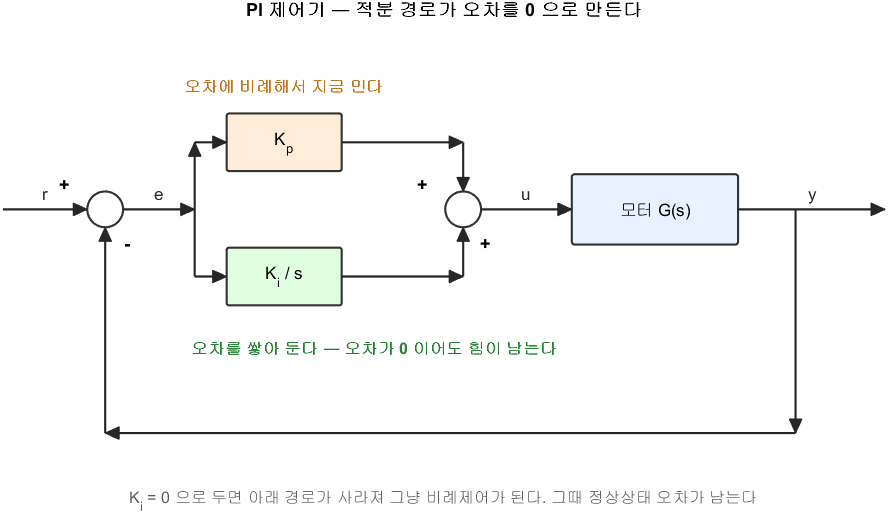

적분 경로를 따로 그려야 Ki 가 무엇을 하는지 보인다

**그림 파일** `w05_pi_loop.png` — `common/dg_pi_loop.m` 의 `dg_pi_loop` · 다시 만들려면 `make_figures('w05_pi_loop')`

**만드는 곳** — `common/dg_pi_loop.m` (`make_figures('w05_pi_loop')`) **직접 확인해 보려면** — `W05_SteadyStateError.slx` 를 열면 **이 그림과 똑같은 블록 배치**가 그대로 있습니다

그림 해석

$K_i$ 하나로 적분기를 켜고 끌 수 있습니다.

- $K_i = 0$ — 순수 비례제어. 정상상태 오차가 남는다

- $K_i > 0$ — 적분기 동작. 오차가 $0$ 으로 간다

확인할 것

- $K_i$ 를 계속 키우면 어떻게 되는가? 이 플랜트에서는 $K_i > 720$ 이면 발산

- 그 한계를 3차 안정 조건으로 손계산해 확인할 수 있다

- 적분기 블록을 지우면 $K_i$ 를 아무리 키워도 오차가 사라지지 않는다

모델은 모델을 열고 `Ctrl+T` 로 실행해도 됩니다. 기본값은 $K_i = 0$ 이라 오차가 남아 있는 것이 보입니다.

## 10-1. 오차상수를 명령으로 구하는 법

정상상태 오차를 손으로 극한 계산할 필요가 없습니다. **개루프 전달함수 **$L(s)$** 에 **$s$** 를 곱한 뒤** `dcgain` **을 부르면 됩니다.**

**주의** — `L` 은 반드시 **개루프**입니다. `feedback` 을 부른 뒤의 폐루프를 넣으면 전혀 다른 값이 나옵니다.

값이 `Inf` 로 나오면 그 입력에 대한 오차가 $0$ 이라는 뜻이고, $0$ 으로 나오면 오차가 무한대로 발산한다는 뜻입니다.

s = tf('s');
[Gm_, ~] = plant_dcmotor('position');
L = 100 * Gm_;

nType = sum(abs(pole(L)) < 1e-9);
fprintf('시스템 타입 : %d\n', nType);

시스템 타입 : 1


fprintf('Kp = %8.4g  -> 계단 오차 1/(1+Kp) = %.4g\n', dcgain(L),      1/(1+dcgain(L)));

Kp =      Inf  -> 계단 오차 1/(1+Kp) = 0


fprintf('Kv = %8.4g  -> 램프 오차 1/Kv     = %.4g\n', dcgain(s*L),    1/dcgain(s*L));

Kv =     9.99  -> 램프 오차 1/Kv     = 0.1001


fprintf('Ka = %8.4g  -> 포물선 오차 1/Ka   = %.4g\n', dcgain(s^2*L),  1/dcgain(s^2*L));

Ka =        0  -> 포물선 오차 1/Ka   = Inf



% 이론값이 실제로 맞는지 램프 응답으로 확인한다
T  = feedback(L, 1);
tr = (0:0.005:60)';
yr = lsim(T, tr, tr);
fprintf('\n램프 입력 실측 오차 : t=20 s 에서 %.4f, t=60 s 에서 %.4f\n', ...
        tr(4001)-yr(4001), tr(end)-yr(end));


램프 입력 실측 오차 : t=20 s 에서 0.1073, t=60 s 에서 0.1002


fprintf('이론값 1/Kv = %.4f  -> 충분히 기다려야 이론값에 닿습니다.\n', 1/dcgain(s*L));

이론값 1/Kv = 0.1001  -> 충분히 기다려야 이론값에 닿습니다.


## 11. 오늘의 정리

- 안정하다 $=$ 폐루프 극점이 전부 좌반면에 있다

- $K$ 를 키우면 극점이 움직인다. 임계이득을 넘으면 불안정

- 3차 안정 조건 $a_2 a_1 > a_3 a_0$. 4차 이상은 `roots` 나 안정여유를 쓴다

- 정상상태 오차는 $L(0)$ 이 무한대면 $0$ 이 된다. 그 장치가 **적분기**

- 원점 극점의 개수가 **시스템 타입**

- 오차상수는 전부 "$L$ 에 $s$ 를 곱하고 $s=0$ 대입"

- 규칙 하나 — **타입 **$N$** 은 **$N$** 차까지의 입력을 오차 없이 따라간다**

- **적분기는 공짜가 아니다.** 타입이 올라갈수록 불안정해지기 쉽다

- 오차 공식은 안정할 때만 의미가 있다

## 12. 다음 주 예고

오늘 $K$ 를 키우며 극점이 움직이는 그림을 그렸습니다. 6주차에서는 그 그림을 **제대로** 그립니다. **근궤적**(root locus)입니다.

그리고 4주차에서 그린 **사양 영역**을 그 위에 겹칩니다.

- 근궤적이 사양 영역을 지나는 지점을 찾는다

- 그 지점의 이득 $K$ 를 읽는다

- **그것이 곧 제어기 설계다**

두 주 동안 준비한 것이 6주차에서 하나로 합쳐집니다.